# Bo

# de plott av transferfunksjon


$$G{\left(s\right)}=\frac{k\cdot \;{\textrm{𝜔}}_n^2 }{s^2 \;+\;2\cdot \;\textrm{𝜁}\cdot \omega {\;}_n \;\cdot \;s\;+\;{\textrm{𝜔}}_n^2 }$$


%num = ;
%den = ; %Hvor polene i transfer funksjonen er.
%system = tf(num,den)
system= tf([1 13 30 0],[1 13 30 -2.51 25.1])

system =
 
           s^3 + 13 s^2 + 30 s
  -------------------------------------
  s^4 + 13 s^3 + 30 s^2 - 2.51 s + 25.1
 
Continuous-time transfer function.



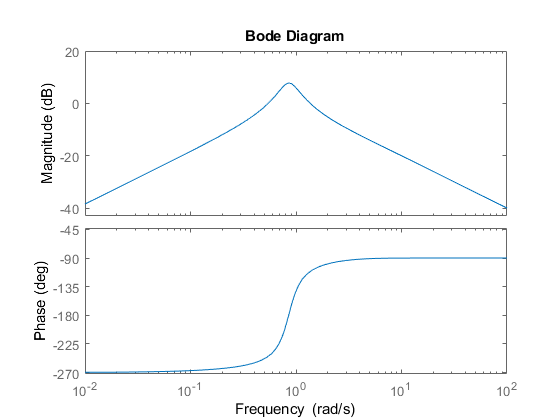


bode(system);

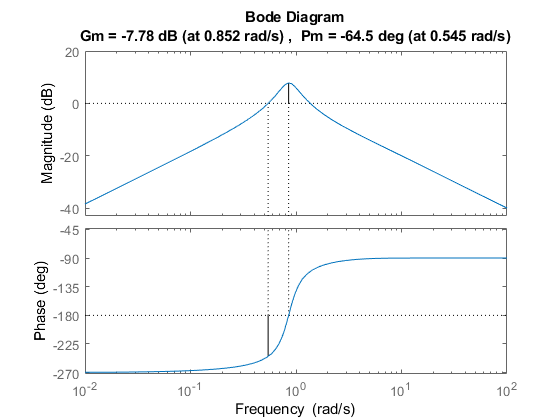

margin(system);

StepRespons:

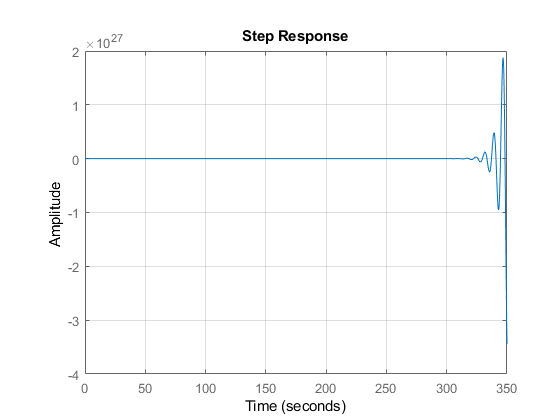

stepRespons = stepplot(system);grid minor;

% Fin regulatpor 

Gc = tf([0.224 0.16788],[1.336 0])

Gc =
 
  0.224 s + 0.1679
  ----------------
      1.336 s
 
Continuous-time transfer function.



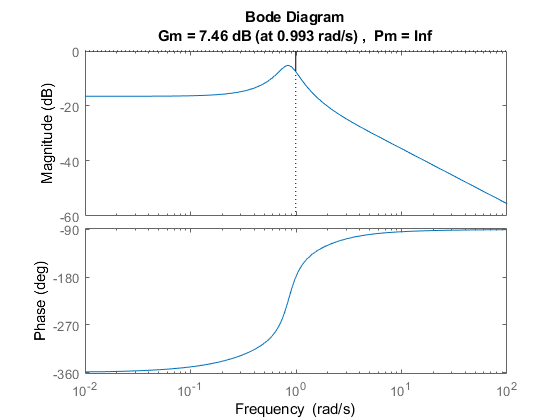

Gtot = system*Gc;

margin(Gtot)

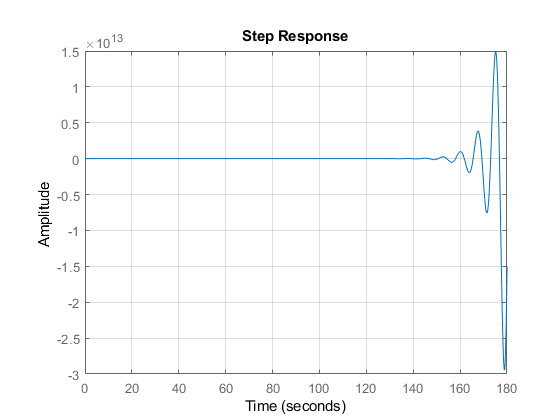

stepRespons = stepplot(Gtot);grid minor;